# Семинар 3. Контейнеры для работы с разнотипными данными

- Несколько примеров итерирования по коллекции

- Распараллеливание циклов

- Объекты для хранения данных разнородных типов

- Ячейки

- Структуры

- Таблицы

- Множества

- Словари

- Использование контейнеров java

#### Дополнительные примеры к предыдущему семинару

Многие функции по умолчанию "воспринимают" матрицу как вектор набор столбцов

clearvars
M3x4 = sym('m',[3,4])

$$M3x4 = \left(\begin{array}{cccc} m_{1,1} & m_{1,2} & m_{1,3} & m_{1,4}\\ m_{2,1} & m_{2,2} & m_{2,3} & m_{2,4}\\ m_{3,1} & m_{3,2} & m_{3,3} & m_{3,4} \end{array}\right)$$

sumM = sum(M3x4)

$$sumM = \left(\begin{array}{cccc} m_{1,1}+m_{2,1}+m_{3,1} & m_{1,2}+m_{2,2}+m_{3,2} & m_{1,3}+m_{2,3}+m_{3,3} & m_{1,4}+m_{2,4}+m_{3,4} \end{array}\right)$$

size(sumM) %- вектор-строка сумм элементов в столбцах

ans =      1     4


prod(M3x4) % 

$$ans = \left(\begin{array}{cccc} m_{1,1}\,m_{2,1}\,m_{3,1} & m_{1,2}\,m_{2,2}\,m_{3,2} & m_{1,3}\,m_{2,3}\,m_{3,3} & m_{1,4}\,m_{2,4}\,m_{3,4} \end{array}\right)$$

 % norm(M3x4)
Mlog = rand(3,6)>0.5

Mlog = 3×6 logical array
   1   1   0   1   1   0
   1   0   0   0   0   1
   1   0   0   0   0   0


all(Mlog)

ans = 1×6 logical array
   1   0   0   0   0   0


all(Mlog,'all')

ans = logical
   0


any(Mlog)

ans = 1×6 logical array
   1   1   0   1   1   1


В цикле "итерирование по коллекции" происходит по столбцам матрицы

clearvars
a_col = sym('a',[3 1])

$$a\_col = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3} \end{array}\right)$$

b_row = sym('b',[1 4])

$$b\_row = \left(\begin{array}{cccc} b_{1} & b_{2} & b_{3} & b_{4} \end{array}\right)$$

M3x4 = sym('m',[3,4])

$$M3x4 = \left(\begin{array}{cccc} m_{1,1} & m_{1,2} & m_{1,3} & m_{1,4}\\ m_{2,1} & m_{2,2} & m_{2,3} & m_{2,4}\\ m_{3,1} & m_{3,2} & m_{3,3} & m_{3,4} \end{array}\right)$$

for a=M3x4
    a % - это столбец матрицы
end

$$a = \left(\begin{array}{c} m_{1,1}\\ m_{2,1}\\ m_{3,1} \end{array}\right)$$

$$a = \left(\begin{array}{c} m_{1,2}\\ m_{2,2}\\ m_{3,2} \end{array}\right)$$

$$a = \left(\begin{array}{c} m_{1,3}\\ m_{2,3}\\ m_{3,3} \end{array}\right)$$

$$a = \left(\begin{array}{c} m_{1,4}\\ m_{2,4}\\ m_{3,4} \end{array}\right)$$

A = a_col*b_row;
B = sym([]);
for b = b_row
    B = [B,a_col*b];
end
A

$$A = \left(\begin{array}{cccc} a_{1}\,b_{1} & a_{1}\,b_{2} & a_{1}\,b_{3} & a_{1}\,b_{4}\\ a_{2}\,b_{1} & a_{2}\,b_{2} & a_{2}\,b_{3} & a_{2}\,b_{4}\\ a_{3}\,b_{1} & a_{3}\,b_{2} & a_{3}\,b_{3} & a_{3}\,b_{4} \end{array}\right)$$

B

$$B = \left(\begin{array}{cccc} a_{1}\,b_{1} & a_{1}\,b_{2} & a_{1}\,b_{3} & a_{1}\,b_{4}\\ a_{2}\,b_{1} & a_{2}\,b_{2} & a_{2}\,b_{3} & a_{2}\,b_{4}\\ a_{3}\,b_{1} & a_{3}\,b_{2} & a_{3}\,b_{3} & a_{3}\,b_{4} \end{array}\right)$$

#### Распараллеливание вычислений при помощи parfor....end

Представляю себе так: 

параллельно запускаются столько матлабов сколько итераций в цикле, на каждом матлабе создается полная копия "внешних" по отношению к телу цикла данных (в данном случае  - это вектор cConst , матрица A, n). Каждый работник не знает о существовании остальных, но знает номер итерации. Порядок выполнения итераций  - произвольный.

*Если происходит распараллеливание на процессах, то примерно так и происходит в реальности, однако количество работников определяется при конфигурации профиля 

**С учетом этого цикл должен работать так, чтобы работники не стукались лбами.**

** основные правила:**

- Вложенные parfor - игнорируются (причем они могут быть где-то дальше по ветке кода)

- Если необходимо в циклах производить "побочные" действия, такие как изменения элементов массива необходимо делать это так, чтобы не могло возникнуть ситуации, когда несколько работников одновременно меняют один и тот же набор эелементов

- *(пункт для порядка) Если в цикле происходят изменения объекта типа "handle", то эти изменения не будут доступны после выполнения цикла, так как каждый работник будет менять свою копию объекта

clearvars
cur_pool = gcp;

Starting parallel pool (parpool) using the 'Threads' profile ...
Connected to parallel pool with 2 workers.


n = 100;
A = zeros(n);
cConst = randn(n,1);
tic
ticBytes;
parfor i=1:n
    Z = rand(n);
    if (norm(Z)/n) > 0.5
        continue
    end
    Z = cConst.*Z;
    % f = A(i+1) - обращение к другому элементу
    A(:,i) = svds(Z,n);
    % break- нельзя!
    % continue  - можно
end
A

A =          0         0   45.9726         0         0         0         0         0   45.9502         0         0   45.6358   45.5322         0         0         0   45.6617         0   45.1017         0         0   45.4723         0         0         0         0         0         0         0   45.8510         0   45.4766         0   45.8850         0         0   45.8771         0         0         0         0   45.9136         0         0         0         0         0         0         0         0
         0         0    7.8239         0         0         0         0         0    8.6018         0         0    7.9849    8.8583         0         0         0    7.6855         0    8.8632         0         0    8.8115         0         0         0         0         0         0         0    7.7673         0    7.9273         0    8.1618         0         0    7.6633         0         0         0         0    8.3294         0         0         0         0         0         0         0     

toc

Elapsed time is 1.441725 seconds.


tocBytes

             BytesSentToWorkers    BytesReceivedFromWorkers
             __________________    ________________________

    Total           NaN                      NaN           



wh = whos("A","cConst");
sum(arrayfun(@(x)x.bytes,wh))*cur_pool.NumWorkers

ans = 161600

cConst = randn(n,1);
A = zeros(n);
tic
for i=1:n
    Z = rand(n);
    if (norm(Z)/n) > 0.5
        continue
    end
    Z = cConst.*Z;
    A(:,i) = svds(Z,n);
end
toc

Elapsed time is 0.121493 seconds.


A

A =          0   50.6851         0         0         0         0         0         0         0         0         0         0         0   50.3611   50.4195         0         0         0         0         0         0         0         0         0         0         0         0         0         0   51.1610   51.0936         0         0         0   51.2999   50.6873   50.6257         0         0         0   50.3323         0         0   50.4133   50.2706   51.2058   51.0145         0         0   50.4700
         0    8.9095         0         0         0         0         0         0         0         0         0         0         0    9.6439    9.2065         0         0         0         0         0         0         0         0         0         0         0         0         0         0    8.4659    9.0235         0         0         0    9.2025    7.6391    9.2052         0         0         0    7.9182         0         0    9.2620    9.7927    9.0375    8.3222         0         0    9

### Контейнеры (встроенные типы для хранения разнородных данных)

### тип cell

Для хранения разнотипных данных  в структуры с числовыми индексами

clearvars
array_of_cell = {'1',"2",3;@peaks,rand(10),figure(10)} % 

array_of_cell = 2×3 cell array
    {'1'   }    {["2"       ]}    {[       3]}
    {@peaks}    {10×10 double}    {1×1 Figure}


array_of_cell(1) % возращает тип cell

ans = 1×1 cell array
    {'1'}


array_of_cell{1} % возвращает содержимое ячейки

ans = '1'

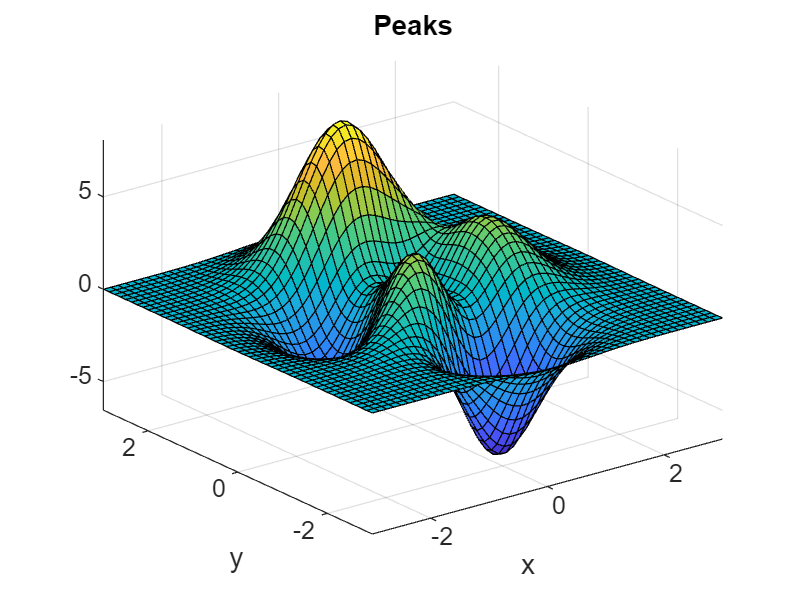

 
z =  3*(1-x).^2.*exp(-(x.^2) - (y+1).^2) ... 
   - 10*(x/5 - x.^3 - y.^5).*exp(-x.^2-y.^2) ... 
   - 1/3*exp(-(x+1).^2 - y.^2) 
 


array_of_cell{2,1}() % вызываем указатель на функцию, который хранится в ячейке

% array_of_cell(1){1} так нельзя
whos array_of_cell

  Name               Size            Bytes  Class    Attributes

  array_of_cell      2x3              1640  cell               



empty_cell = {};
whos empty_cell

  Name            Size            Bytes  Class    Attributes

  empty_cell      0x0                 0  cell               



empty_cell{1} = true

empty_cell = 1×1 cell array
    {[1]}


whos empty_cell

  Name            Size            Bytes  Class    Attributes

  empty_cell      1x1               105  cell               



Массив ячеек

clearvars
array_of_cell = {'1',"2",3;@peaks,rand(10),figure(10)} % 

array_of_cell = 2×3 cell array
    {'1'   }    {["2"       ]}    {[       3]}
    {@peaks}    {10×10 double}    {1×1 Figure}


array_of_cell_of_cell = {array_of_cell;array_of_cell} % заворачивает cell в cell => массив ячеек массивов ячеек

array_of_cell_of_cell = 2×1 cell array
    {2×3 cell}
    {2×3 cell}


array_of_cell_concat = [array_of_cell;array_of_cell] % матрица ячеек

array_of_cell_concat = 4×3 cell array
    {'1'   }    {["2"       ]}    {[       3]}
    {@peaks}    {10×10 double}    {1×1 Figure}
    {'1'   }    {["2"       ]}    {[       3]}
    {@peaks}    {10×10 double}    {1×1 Figure}


 
z =  3*(1-x).^2.*exp(-(x.^2) - (y+1).^2) ... 
   - 10*(x/5 - x.^3 - y.^5).*exp(-x.^2-y.^2) ... 
   - 1/3*exp(-(x+1).^2 - y.^2) 
 


array_of_cell_concat{2,1}() % - вызываем содержимое ячейки (а там - указатель на функцию peaks)

clearvars
folder = get_folder()

folder = 'E:\projects\matlab-seminar\basics\sem1_4'

full_file = fullfile(folder,"tbl.xls")

full_file = "E:\projects\matlab-seminar\basics\sem1_4\tbl.xls"

cell_1 = cell(21,6);
cell_1(2:end,:) = num2cell(rand([20 6]));
cell_1(1,:) = {"а" "ё" "а" "а" "и" "л" };
writecell(cell_1,full_file);
tbl1 = readcell(full_file)

tbl1 = 21×6 cell array
    {'а'     }    {'ё'     }    {'а'     }    {'а'     }    {'и'     }    {'л'     }
    {[0.1579]}    {[0.3411]}    {[0.7704]}    {[0.4784]}    {[0.5980]}    {[0.7257]}
    {[0.4035]}    {[0.5090]}    {[0.7850]}    {[0.3986]}    {[0.8820]}    {[0.3565]}
    {[0.6916]}    {[0.6701]}    {[0.6412]}    {[0.2624]}    {[0.3666]}    {[0.4846]}
    {[0.6717]}    {[0.4551]}    {[0.1673]}    {[0.4474]}    {[0.8094]}    {[0.0896]}
    {[0.1296]}    {[0.2154]}    {[0.7788]}    {[0.8287]}    {[0.9533]}    {[0.9392]}
    {[0.1315]}    {[0.7423]}    {[0.4132]}    {[0.7783]}    {[0.4142]}    {[0.4759]}
    {[0.0658]}    {[0.0498]}    {[0.2476]}    {[0.0988]}    {[0.9220]}    {[0.0484]}
    {[0.5994]}    {[0.4866]}    {[0.7754]}    {[0.4132]}    {[0.6101]}    {[0.4499]}
    {[0.8751]}    {[0.5866]}    {[0.7287]}    {[0.3798]}    {[0.5516]}    {[0.2596]}
    {[0.6529]}    {[0.8927]}    {[0.9827]}    {[0.1010]}    {[0.8951]}    {[0.1940]}
    {[0.1435]}    {[0.4963]}    {[0.6627]}

help("readcell")

 readcell Create a cell array by reading from a file.
 
    Use the readcell function to create a cell array by reading
    column-oriented data from a file. readcell can automatically determine
    the file format from its extension.
 
    C = readcell(FILENAME) creates a cell array by reading from a file.
    FILENAME can be one of these:
 
        - For local files, FILENAME can be an absolute path that contains
          a filename and file extension. FILENAME can also be a relative
          path to the current directory or to a directory on the MATLAB
          path. For example, to import a file on the MATLAB path:
 
             C = readcell("patients.xls");
 
        - For files from an Internet URL or stored at a remote location,
          FILENAME must be a full path using a Uniform Resource Locator
          (URL). For example, to import a remote file from Amazon S3,
          specify the full URL for the f

Пример  использования "cell"    - splat аргументов функции

% Пример  - splat аргументов функции
A = rand(1,5);
varar_fun(A(:))

arg1
    0.1308
    0.3066
    0.8220
    0.6477
    0.8242



C = num2cell(A);
varar_fun(C{:})

arg1
    0.1308

arg2
    0.3066

arg3
    0.8220

arg4
    0.6477

arg5
    0.8242



#### тип struct

Для хранения разнородных данных по имени

clearvars
struct_scalar = struct("field1",rand(10),"field2",'Содержимое ячейки 2',"field3",[], "peaks_handle",@peaks) % стурктура с полями

struct_scalar = struct with fields:
          field1: [10×10 double]
          field2: 'Содержимое ячейки 2'
          field3: []
    peaks_handle: @peaks


struct_scalar.field1 % получение данных из поля по названию поля

ans =     0.9078    0.4437    0.9992    0.9192    0.6897    0.5994    0.6507    0.1215    0.3122    0.7220
    0.4963    0.7163    0.3474    0.4753    0.8266    0.9062    0.3988    0.0017    0.4530    0.5066
    0.4123    0.6361    0.1805    0.4898    0.4630    0.9150    0.0410    0.9195    0.0981    0.7198
    0.5970    0.7536    0.1480    0.1114    0.5880    0.1713    0.8793    0.2274    0.5330    0.6508
    0.6986    0.7119    0.6425    0.8446    0.0915    0.6738    0.5747    0.9306    0.9019    0.3862
    0.3832    0.5301    0.2870    0.3813    0.8738    0.6167    0.3730    0.9124    0.9371    0.0631
    0.2117    0.6986    0.7402    0.9084    0.3299    0.0043    0.6738    0.5414    0.4662    0.8431
    0.8128    0.2957    0.4429    0.2888    0.9349    0.3130    0.6583    0.6350    0.0364    0.5363
    0.5490    0.3938    0.5928    0.2630    0.5273    0.5833    0.9940    0.5501    0.7201    0.6949
    0.6051    0.2344    0.2794    0.5607    0.7175    0.0785    0.6297    0.1351    0

names_of_fields = fieldnames(struct_scalar) % возвращает имена полей

names_of_fields = 4×1 cell array
    {'field1'      }
    {'field2'      }
    {'field3'      }
    {'peaks_handle'}


struct_scalar.(names_of_fields{2}) % имена можно задавать в виде символов,но это несколько медленнее

ans = 'Содержимое ячейки 2'

 
z =  3*(1-x).^2.*exp(-(x.^2) - (y+1).^2) ... 
   - 10*(x/5 - x.^3 - y.^5).*exp(-x.^2-y.^2) ... 
   - 1/3*exp(-(x+1).^2 - y.^2) 
 


struct_scalar.peaks_handle()

Массив структур

clearvars
struct_scalar = struct("field1",rand(),"field2",'Содержимое ячейки 2',"field3",[], "peaks_handle",@peaks) % стурктура с полями

struct_scalar = struct with fields:
          field1: 0.4662
          field2: 'Содержимое ячейки 2'
          field3: []
    peaks_handle: @peaks


struct_array_empty(10) = struct_scalar % резервирование памяти путем обратного индексирования  - для структур довольно удобно

struct_array_empty = 1×10 struct array with fields:
    field1
    field2
    field3
    peaks_handle


% так как массив структур имеет все те же имена полей 
struct_array_filled(10:-1:1) = struct_scalar

struct_array_filled = 1×10 struct array with fields:
    field1
    field2
    field3
    peaks_handle


isfield(struct_scalar,"a")

ans = logical
   0


struct_array_filled(3).field4 = "f" % новое поле добавилось ко всем элементам 

struct_array_filled = 1×10 struct array with fields:
    field1
    field2
    field3
    peaks_handle
    field4


struct_array_filled(end).field1=rand();
struct_array_filled(1).field1=1;
a = struct_array_filled(:).field1 % возвращает первый элемент

a = 1

a(10:-1:1)=struct_array_filled(:).field1 % тут не получилось

a =      1     1     1     1     1     1     1     1     1     1


a= [struct_array_filled(:).field1] % list comprehention

a =     1.0000    0.4662    0.4662    0.4662    0.4662    0.4662    0.4662    0.4662    0.4662    0.8800



% varar_fun - показывает свои аргументы по одному
varar_fun("первый аргумент", pi)

arg1
первый аргумент
arg2
    3.1416



varar_fun(struct_array_filled(:).field1)  % можно использовать аналогично {:} для передачи большого числа аргументов по одному (splat -функция)

arg1
     1

arg2
    0.4662

arg3
    0.4662

arg4
    0.4662

arg5
    0.4662

arg6
    0.4662

arg7
    0.4662

arg8
    0.4662

arg9
    0.4662

arg10
    0.8800



# Выводы по семинару 3.

- Если есть "parallel computing toolbox", то можно распараллеливать вычисления при помощи **parfor...continue....end. **Основной принцип расботы с параллельными циклами - нобходимо помнить, что итерации цикла выполняются независимо друг от друга и нельзя чтобы в коде цикла могла возникнуть ситуация, когда параллельные процессы конкурируют за один и тот же элемент массива

- Для хранения разнотипных данных в объектах с индексированием по типу массивов можно пользоваться массивом ячеек, тип **cell, **для которого существуют два способа индексирования (i,j) - возвращает элемент массива с типом **cell**, {i,j} - вытаскивает содержимое ячейки. Индексирование с круглыми скобками позволяет делать все те же операции с массивом ячеек, что и с массивом чисел.

- Тип **cell **используется для передаче функции произвольного числа аргументов, для передачи аргументов по одному можно использовать **splat** - функцию **{:}**

- Тип **struct** - для хранения разнотипных данных в массиве с "индексированием" при помощи имени. Может также использоваться для передаче большого числа аргументом по одному 

function return_value = like_example(be_like_me)
    return_value = zeros(numel(be_like_me),'like',be_like_me);
    return_value = return_value*be_like_me(:);
end
function A = fill_by_row()
    N = 5000;
    A = zeros(N);
    for iii=1:N % внешний цикл перебирает строки
        for jjj=1:N
            A(iii,jjj) = 5;
        end
    end
end
function A = fill_by_column()
    N = 5000;
    A = zeros(N);
    for jjj=1:N % внешний цикл перебирает колонки
        for iii=1:N
            A(iii,jjj) = 5;
        end
    end
end
function A=fill_by_column_no_memalloc()
    N = 5000;
    for jjj=1:N % внешний цикл перебирает колонки
        for iii=1:N
            A(iii,jjj) = 5;
        end
    end    
end
function MAT=fill_by_column_reverse_order()
    N = 5000;
    for jjj=N:-1:1 % внешний цикл перебирает колонки
        for iii=N:-1:1
            MAT(iii,jjj) = 5;
        end
    end    
end

function [r_str,r_ch] = gen_random_string(N)
        alfabeth = 'a':'y';
        n = numel(alfabeth);
        rand_inds = randi(n,[1,N]);
        r_ch = alfabeth(rand_inds);
        r_str = string(r_ch);
end

%% Сравнение операций, выполняемых непосредственно для всей матрицы и перебором элементов матрицы
function A = sin_in_circle(A)
    N = size(A);
    for jjj=1:N(2) % внешний цикл перебирает колонки
        for iii=1:N(1)
            A(iii,jjj) = sin(A(iii,jjj));
        end
    end
end
function A = sin_direct(A)
    A = sin(A);
end
function A = sin_in_circle_line_index(A)
    N = numel(A);
    for iii=1:N
        A(iii) = sin(A(iii));
    end
end
%
function out = ALL(A)
    out = sum(A,'all');
end
% что быстрей итерирование по коллекции или итерирование с индексацией
function s = indexwise_iter() % индексирование по индексам
    A = rand(100000,1);
    s=0;
    for iii = 1:numel(A)
        s = s+ A(iii);
    end
end
function s = elementwise_iter()
    A = rand(100000,1);
    s=0;
    for a = transpose(A)
        s = s+ a;
    end
end
% Пример исопльзования структур типа cell  - функция с произвольным числом
% аргументов
function varar_fun(varargin)
    counter = 0;
    for arg = varargin
        counter = counter + 1;
        disp("arg" + counter);
        disp(arg{1})
    end
end

function folder = get_folder()
% текущая папка
folder = fileparts(matlab.desktop.editor.getActiveFilename);
end